% === 有极化信息的干扰与目标仿真 ===
close all; clear; clc
j = sqrt(-1);

fs = 100e6;           % 采样频率
ts = 1/fs;
B = 10e6;             % 带宽
fc = 40e6;            % 中心频率
label = 17;           % FJ_DFTJ

% === LFM脉冲 ===
taup = 10e-6;         % LFM脉宽
Ntau = round(taup * fs);
ttau = (-Ntau/2 : Ntau/2-1) * ts;
lfm = exp(1j*pi*B/taup * ttau.^2);  % 基带LFM脉冲

% === 多脉冲参数 ===
Np = 16;                     
PRI = 200e-6;                 
PRI_samp = round(PRI * fs);
N_total = Np * PRI_samp;
t_total = (0:N_total-1) * ts;

% === 极化参数定义 ===
% 目标极化：近似水平线极化
theta_tar = 10*pi/180; phi_tar = 0;        
% 干扰极化：右旋圆极化
theta_jam = 45*pi/180; phi_jam = pi/2;     

p_tar = [cos(theta_tar); exp(1j*phi_tar)*sin(theta_tar)];
p_jam = [cos(theta_jam); exp(1j*phi_jam)*sin(theta_jam)];

% === 构造目标信号 ===
tx = zeros(1, N_total);
target_start_idx_in_PRI = round(taup*5*fs);
for k = 0:Np-1
    start_idx = k * PRI_samp + target_start_idx_in_PRI;
    tx(start_idx : start_idx + Ntau - 1) = lfm;
end

% === 噪声与干扰参数 ===
SNR = 50;
JNR = 15;
data_num = 3; % 干扰机数量

As = 10^(SNR/20);
JNRa = 35;
Aja = 10^(JNRa/20);

% === 生成干扰信号 ===
Bj = 20e6;
lpFilt = fir1(34, Bj/(fs), chebwin(35,30)); 

jam = zeros(data_num,N_total);
k = 64;  
inte_time = 1e-7;
time = (k-1)*inte_time + taup;
lfm_d = zeros(1,round(time*fs));
lfm_dt = zeros(1,round(3*time*fs));

for i =1:3*k
    left = (i-1)*inte_time*fs + 1;
    right = left + Ntau -1;
    lfm_dt(left:right) = lfm_dt(left:right) + lfm;
end

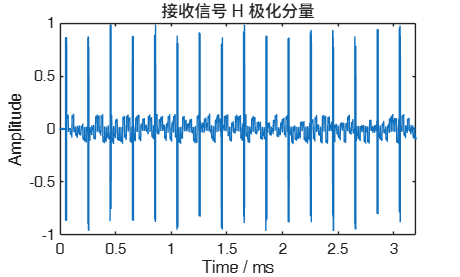

lfm_d(1:round(time*fs)) = lfm_dt(Ntau+1:Ntau+round(time*fs));
Ndelay = length(lfm_d);
jam_mat = [lfm_d ,zeros(1,2*Ndelay);zeros(1,Ndelay),lfm_d,zeros(1,Ndelay);zeros(1,2*Ndelay),lfm_d];

for m = 1:data_num
    sp = randn([1,N_total]) + 1j*randn([1,N_total]);
    sp = sp / std(sp);
    jam_signal = zeros(1, N_total+PRI_samp);

    delay_samp = 3*Ndelay;
    left_range = target_start_idx_in_PRI + Ndelay*(m-1) + Ntau +1;
    right_range = left_range + length(jam_mat(m,:));
    
    phi = 2 * pi * rand;  
    lfm_with_phase = jam_mat(m,:) * exp(1j * phi);
    Aj = 10^((JNR)/20);
    jam_signal(left_range:right_range-1) = jam_signal(left_range:right_range-1) + Aj * lfm_with_phase;

    while right_range <= N_total
        left_range = left_range + delay_samp ;
        right_range = left_range + length(jam_mat(m,:));
        phi = 2 * pi * rand;  
        lfm_with_phase = jam_mat(m,:) * exp(1j * phi);
        r = -0.5 + 1 * rand;
        Aj = 10^((JNR+ r)/20);
        jam_signal(left_range:right_range-1) = jam_signal(left_range:right_range-1) + Aj * lfm_with_phase;
    end
    jam(m, 1:N_total) = jam_signal(1:N_total) + sp;
end

% === 叠加目标与干扰（极化域） ===
tx_pol = p_tar * tx;                     % 2×N_total
jam_pol = zeros(2, N_total);
for m = 1:data_num
    jam_pol = jam_pol + p_jam * jam(m,:);
end

% 加上极化噪声
n_pol = (randn(2,N_total) + 1j*randn(2,N_total))/sqrt(2);

rx_pol = As*tx_pol + jam_pol + n_pol;
rx_pol = rx_pol / max(abs(rx_pol(:)));

% === 可视化 ===
figure;
plot(t_total*1e3, real(rx_pol(1,:)));
xlabel('Time / ms'); ylabel('Amplitude');
title('接收信号 H 极化分量');

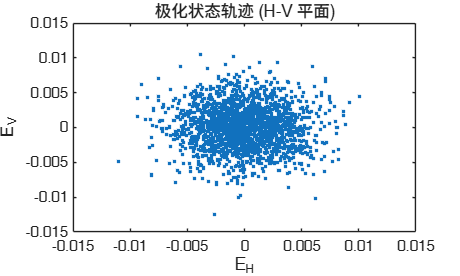


figure;
plot(real(rx_pol(1,1:2000)), real(rx_pol(2,1:2000)), '.');
xlabel('E_H'); ylabel('E_V');
title('极化状态轨迹 (H-V 平面)');

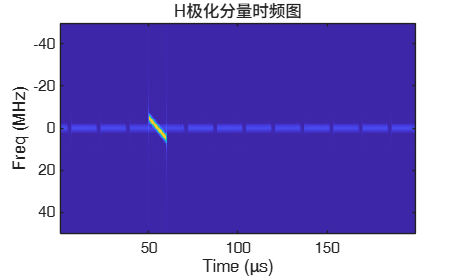


figure;
[S,F,T] = spectrogram(rx_pol(1, PRI_samp+1:2*PRI_samp), 64, 60, 256, fs, 'centered');
imagesc(T*1e6, F/1e6, abs(S));
ylabel('Freq (MHz)'); xlabel('Time (μs)');
title('H极化分量时频图');

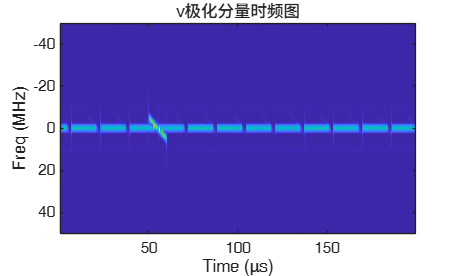


figure;
[S,F,T] = spectrogram(rx_pol(2, PRI_samp+1:2*PRI_samp), 64, 60, 256, fs, 'centered');
imagesc(T*1e6, F/1e6, abs(S));
ylabel('Freq (MHz)'); xlabel('Time (μs)');
title('v极化分量时频图');